Computation Vision - Project 1 Report

Topic B:  Railway inspection using on-train cameras

Authors:

- David Marafuz Gaspar - 106541 - david.marafuz.gaspar@tecnico.ulisboa.pt

- Pedro Gaspar Monico - 106626 - pedro.monico@tecnico.ulisboa.pt

Supervisors:

- Prof. Alexandra Moutinho

- Eng. Alexandre Athayde

## Introduction

With the growth of railway systems in developed countries, and the recent expansion in developing nations, the safe and efficient operation of railway networks is paramount for passenger transport. To encourage the use of public transportation, it is very important to ensure the safety of the ridership. A critical aspect of this safety is ensuring that the track ahead is clear of obstructions, such as fallen trees, rocks, or debris, which could lead to catastrophic derailments. Traditionally, this inspection relies on periodic human patrols or trackside sensors, methods that can be time-consuming, costly, and lack the ability to provide real-time information to an oncoming train. Computer vision offers an alternative, as it can be automated without the high cost of continuous human resources.

This project aims to use image processing techniques to classify images of real railway tracks by detecting obstructions that could interfere with the passage of trains, ultimately enhancing the safety of this mode of transportation. The work will focus on several key problems: analyzing the images to characterize the appearance of the rails, and designing an algorithm to segment the image and isolate the rails. Subsequently, methods to determine whether the identified rail path is free of obstructions will be explored, not only checking if the rail itself is obstructed, but also detecting objects on the sides and in the area between the rails that could interfere with the train's path. The performance of the developed procedure will be quantitatively evaluated against our own annotated ground truth data using standard metrics.

This report is structured as follows [**FINISH THIS HERE**] Section 2 details the methodology and image processing tools employed in the development pipeline. Section 3 presents the results of the implemented algorithms and their performance analysis. Finally, Section 4 concludes the report with a summary of findings and a discussion of potential future improvements

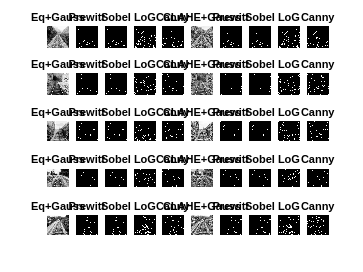


clear; clc; close all;

% =========================
% LOAD DATA
% =========================

filenames = {
    './Data/cortada11.png'
    './Data/Frame1253.jpg'
    './Data/Frame1291.jpg'
    './Data/Frame1532.jpg'
    './Data/Frame1603.jpg'
    './Data/Frame1616.jpg'
    './Data/image00756.jpg'
    './Data/image02293.jpg'
    './Data/image04054.jpg'
    './Data/image04925.jpg'
    './Data/image06026.jpg'
    './Data/j30.jpg'
    './Data/l20.jpg'
    './Data/l23.jpg'
    './Data/p8.jpg'
};

labels = [1 0 0 0 0 1 0 0 1 0 0 1 1 1 1];

N = length(filenames);

images = cell(N,1);
for i = 1:N
    images{i} = imread(filenames{i});
end

% =========================
% GRAYSCALE
% =========================

images_gray = cell(N,1);
for i = 1:N
    images_gray{i} = rgb2gray(images{i});
end

% =========================
% PARAMETERS
% =========================

CLAHE_TILES = [8 8];
CLAHE_CLIPLIMIT = 0.02;
SIGMA = 1.5;

SIGMA1 = 1;
SIGMA2 = 2;

SELECTED = [2 10 1 13 4];

% =========================
% PROCESSING
% =========================

images_eq = cell(N,1);
images_clahe = cell(N,1);
images_eq_gauss = cell(N,1);
images_clahe_gauss = cell(N,1);
images_dog = cell(N,1);

for i = 1:N
    img = images_gray{i};

    images_eq{i} = histeq(img);

    images_clahe{i} = adapthisteq(img, ...
        'NumTiles', CLAHE_TILES, ...
        'ClipLimit', CLAHE_CLIPLIMIT);

    images_eq_gauss{i} = imgaussfilt(images_eq{i}, SIGMA);
    images_clahe_gauss{i} = imgaussfilt(images_clahe{i}, SIGMA);

    g1 = imgaussfilt(img, SIGMA1);
    g2 = imgaussfilt(img, SIGMA2);
    images_dog{i} = imsubtract(g1, g2);
end

% =========================
% EDGE DETECTION
% =========================

edges_eq.prewitt = cell(N,1);
edges_eq.sobel   = cell(N,1);
edges_eq.log     = cell(N,1);
edges_eq.canny   = cell(N,1);

edges_clahe.prewitt = cell(N,1);
edges_clahe.sobel   = cell(N,1);
edges_clahe.log     = cell(N,1);
edges_clahe.canny   = cell(N,1);

for i = 1:N
    img_eq = images_eq_gauss{i};
    img_clahe = images_clahe_gauss{i};

    edges_eq.prewitt{i} = edge(img_eq, 'prewitt');
    edges_eq.sobel{i}   = edge(img_eq, 'sobel');
    edges_eq.log{i}     = edge(img_eq, 'log');
    edges_eq.canny{i}   = edge(img_eq, 'canny', [0.15 0.4], 2);
    edges_eq.canny{i}   = bwareaopen(edges_eq.canny{i}, 50);

    edges_clahe.prewitt{i} = edge(img_clahe, 'prewitt');
    edges_clahe.sobel{i}   = edge(img_clahe, 'sobel');
    edges_clahe.log{i}     = edge(img_clahe, 'log');
    edges_clahe.canny{i}   = edge(img_clahe, 'canny', [0.15 0.4], 2);
    edges_clahe.canny{i}   = bwareaopen(edges_clahe.canny{i}, 50);
end

% =========================
% OTSU
% =========================

images_otsu_eq = cell(N,1);
images_otsu_clahe = cell(N,1);
images_otsu_dog = cell(N,1);

for i = 1:N
    level_eq = graythresh(images_eq_gauss{i});
    images_otsu_eq{i} = imbinarize(images_eq_gauss{i}, level_eq);

    level_clahe = graythresh(images_clahe_gauss{i});
    images_otsu_clahe{i} = imbinarize(images_clahe_gauss{i}, level_clahe);

    level_dog = graythresh(images_dog{i});
    images_otsu_dog{i} = imbinarize(images_dog{i}, level_dog);

    images_otsu_eq{i} = bwareaopen(images_otsu_eq{i}, 50);
    images_otsu_clahe{i} = bwareaopen(images_otsu_clahe{i}, 50);
    images_otsu_dog{i} = bwareaopen(images_otsu_dog{i}, 50);
end

% =========================
% VISUALIZATION - EDGES
% =========================

figure;

for row = 1:length(SELECTED)
    i = SELECTED(row);

    subplot(length(SELECTED),10,(row-1)*10 + 1);
    imshow(images_eq_gauss{i}); title('Eq+Gauss');

    subplot(length(SELECTED),10,(row-1)*10 + 2);
    imshow(edges_eq.prewitt{i}); title('Prewitt');

    subplot(length(SELECTED),10,(row-1)*10 + 3);
    imshow(edges_eq.sobel{i}); title('Sobel');

    subplot(length(SELECTED),10,(row-1)*10 + 4);
    imshow(edges_eq.log{i}); title('LoG');

    subplot(length(SELECTED),10,(row-1)*10 + 5);
    imshow(edges_eq.canny{i}); title('Canny');

    subplot(length(SELECTED),10,(row-1)*10 + 6);
    imshow(images_clahe_gauss{i}); title('CLAHE+Gauss');

    subplot(length(SELECTED),10,(row-1)*10 + 7);
    imshow(edges_clahe.prewitt{i}); title('Prewitt');

    subplot(length(SELECTED),10,(row-1)*10 + 8);
    imshow(edges_clahe.sobel{i}); title('Sobel');

    subplot(length(SELECTED),10,(row-1)*10 + 9);
    imshow(edges_clahe.log{i}); title('LoG');

    subplot(length(SELECTED),10,(row-1)*10 + 10);
    imshow(edges_clahe.canny{i}); title('Canny');
end

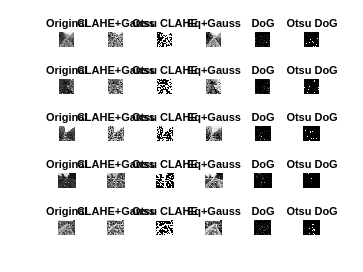


% =========================
% VISUALIZATION - OTSU + DoG
% =========================

figure;

for row = 1:length(SELECTED)
    i = SELECTED(row);

    subplot(length(SELECTED),6,(row-1)*6 + 1);
    imshow(images_gray{i}); title('Original');

    subplot(length(SELECTED),6,(row-1)*6 + 2);
    imshow(images_clahe_gauss{i}); title('CLAHE+Gauss');

    subplot(length(SELECTED),6,(row-1)*6 + 3);
    imshow(images_otsu_clahe{i}); title('Otsu CLAHE');

    subplot(length(SELECTED),6,(row-1)*6 + 4);
    imshow(images_eq_gauss{i}); title('Eq+Gauss');

    subplot(length(SELECTED),6,(row-1)*6 + 5);
    imshow(images_dog{i}, []); title('DoG');

    subplot(length(SELECTED),6,(row-1)*6 + 6);
    imshow(images_otsu_dog{i}); title('Otsu DoG');
end

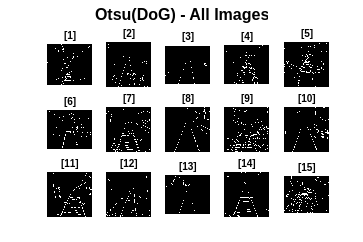


% =========================
% GRID VISUALIZATION: Otsu(DoG) ONLY
% =========================

figure('Name','Otsu(DoG) Grid','NumberTitle','off','Position',[0 0 1800 1200]);

cols = 5; % número de colunas na grid
rows = ceil(N / cols);

for i = 1:N
    subplot(rows, cols, i);
    imshow(images_otsu_dog{i});
    title(sprintf('[%d]', i),'FontSize',8);
end

sgtitle('Otsu(DoG) - All Images','FontSize',12,'FontWeight','bold');

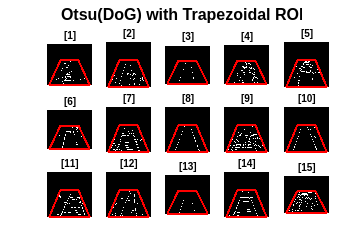


% =========================
% ROI PARAMETERS (fractions of image size)
% =========================

ROI_BL_X = 0.05;   % bottom-left
ROI_BR_X = 0.95;   % bottom-right
ROI_TL_X = 0.30;   % top-left
ROI_TR_X = 0.70;   % top-right
ROI_TOP_Y = 0.4;   % top y fraction

% =========================
% APPLY ROI TO Otsu(DoG) AND DISPLAY
% =========================

figure('Name','Otsu(DoG) with ROI','NumberTitle','off','Position',[0 0 1800 1200]);

cols = 5; % 5 imagens por linha
rows = ceil(N/cols);

for i = 1:N
    bw = images_otsu_dog{i};
    [h, w] = size(bw);

    % ROI vertices in pixels
    roi_x = [ROI_BL_X*w, ROI_BR_X*w, ROI_TR_X*w, ROI_TL_X*w];
    roi_y = [h, h, ROI_TOP_Y*h, ROI_TOP_Y*h];

    % Create binary mask
    mask = poly2mask(roi_x, roi_y, h, w);

    % Apply mask
    bw_roi = bw & mask;

    % Display
    subplot(rows, cols, i);
    imshow(bw_roi);
    hold on;
    % Display ROI polygon outline on top
    plot([roi_x roi_x(1)], [roi_y roi_y(1)], 'r-', 'LineWidth', 1.5);
    hold off;
    title(sprintf('[%d]', i),'FontSize',8);
end

sgtitle('Otsu(DoG) with Trapezoidal ROI','FontSize',12,'FontWeight','bold');

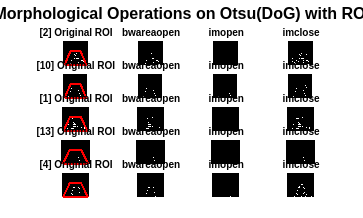


% =========================
% MORPHOLOGICAL OPERATIONS TEST
% =========================

SELECTED = [2 10 1 13 4];

% ROI trapezoid parameters
ROI_BL_X = 0.05; ROI_BR_X = 0.95;
ROI_TL_X = 0.30; ROI_TR_X = 0.70;
ROI_TOP_Y = 0.4;

% Parameters for morphology
min_pixels = 100;           % for bwareaopen
strel_radius = 3;          % for imopen and imclose
se = strel('disk', strel_radius);

figure('Name','Morphological Operations Comparison','NumberTitle','off','Position',[0 0 2000 1200]);

for row = 1:length(SELECTED)
    i = SELECTED(row);
    bw = images_otsu_dog{i};
    [h, w] = size(bw);

    % ROI mask
    roi_x = [ROI_BL_X*w, ROI_BR_X*w, ROI_TR_X*w, ROI_TL_X*w];
    roi_y = [h, h, ROI_TOP_Y*h, ROI_TOP_Y*h];
    mask = poly2mask(roi_x, roi_y, h, w);

    % Apply ROI
    bw_roi = bw & mask;

    % ---- 1. bwareaopen ----
    bw_bwarea = bwareaopen(bw_roi, min_pixels);

    % ---- 2. imopen ----
    bw_open = imopen(bw_roi, se);

    % ---- 3. imclose ----
    bw_close = imclose(bw_roi, se);

    % Display results in grid
    subplot(length(SELECTED), 4, (row-1)*4 + 1);
    imshow(bw_roi);
    hold on; plot([roi_x roi_x(1)], [roi_y roi_y(1)], 'r-', 'LineWidth', 1.5);
    title(sprintf('[%d] Original ROI', i),'FontSize',8);
    hold off;

    subplot(length(SELECTED), 4, (row-1)*4 + 2);
    imshow(bw_bwarea);
    title('bwareaopen','FontSize',8);

    subplot(length(SELECTED), 4, (row-1)*4 + 3);
    imshow(bw_open);
    title('imopen','FontSize',8);

    subplot(length(SELECTED), 4, (row-1)*4 + 4);
    imshow(bw_close);
    title('imclose','FontSize',8);
end

sgtitle('Morphological Operations on Otsu(DoG) with ROI','FontSize',12,'FontWeight','bold');

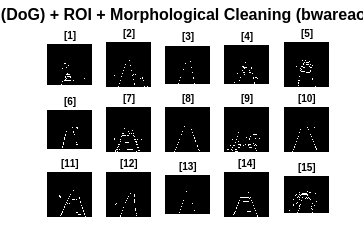



% =========================
% CREATE CLEANED Otsu(DoG) WITH ROI FOR ALL IMAGES
% =========================

ROI_BL_X = 0.05; ROI_BR_X = 0.95;
ROI_TL_X = 0.30; ROI_TR_X = 0.70;
ROI_TOP_Y = 0.4;
min_pixels = 100;

images_otsu_dog_roi_clean = cell(N,1);

for i = 1:N
    bw = images_otsu_dog{i};
    [h, w] = size(bw);

    % ROI mask
    roi_x = [ROI_BL_X*w, ROI_BR_X*w, ROI_TR_X*w, ROI_TL_X*w];
    roi_y = [h, h, ROI_TOP_Y*h, ROI_TOP_Y*h];
    mask = poly2mask(roi_x, roi_y, h, w);

    % Apply ROI and remove small objects
    images_otsu_dog_roi_clean{i} = bwareaopen(bw & mask, min_pixels);
end

% =========================
% DISPLAY GRID - ALL IMAGES
% =========================

cols = 5; % 5 imagens por linha
rows = ceil(N / cols);

figure('Name','Final Otsu(DoG) with ROI Cleaned','NumberTitle','off','Position',[0 0 1800 1200]);

for i = 1:N
    subplot(rows, cols, i);
    imshow(images_otsu_dog_roi_clean{i});
    title(sprintf('[%d]', i),'FontSize',8);
end

sgtitle('Otsu(DoG) + ROI + Morphological Cleaning (bwareaopen)','FontSize',12,'FontWeight','bold');

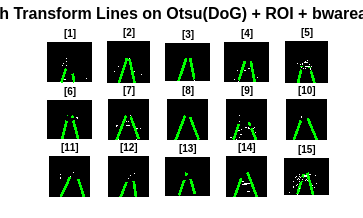


% =========================
% HOUGH TRANSFORM ON CLEANED Otsu(DoG)
% =========================

figure('Name','Hough Transform Lines','NumberTitle','off','Position',[0 0 2000 1200]);

cols = 5;
rows = ceil(N / cols);

for i = 1:N
    bw_clean = images_otsu_dog_roi_clean{i};

    % Compute Hough Transform
    [H,theta,rho] = hough(bw_clean);

    % Find peaks
    P = houghpeaks(H, 2, 'Threshold', ceil(0.3*max(H(:))));

    % Extract lines
    lines = houghlines(bw_clean, theta, rho, P, 'FillGap', 5, 'MinLength', 20);

    % Display
    subplot(rows, cols, i);
    imshow(bw_clean); hold on;

    for k = 1:length(lines)
        xy = [lines(k).point1; lines(k).point2];
        plot(xy(:,1), xy(:,2), 'LineWidth', 2, 'Color', 'green');
    end

    title(sprintf('[%d]', i),'FontSize',8);
    hold off;
end

sgtitle('Hough Transform Lines on Otsu(DoG) + ROI + bwareaopen','FontSize',12,'FontWeight','bold');


% =========================
% Hough + ROI + Strips + Top 2 Lines + Metrics + Ground Truth
% =========================

cols = 5;
rows = ceil(N/cols);

% ROI trapezoid parameters
ROI_BL_X = 0.05; ROI_BR_X = 0.95;
ROI_TL_X = 0.3;  ROI_TR_X = 0.7;
ROI_TOP_Y = 0.45;

min_pixels = 100;
theta_min = -50;
theta_max = 50;
x_thresh = 20;      % distância mínima entre linhas
n_strips = 3;       % número de strips

% Prepara tabela para métricas
metric_table = table('Size',[N*n_strips, 7], ...
    'VariableTypes',{'double','double','double','double','double','double','string'}, ...
    'VariableNames',{'Image','Strip','NumLines','MeanLength','MaxLength','CoverageFraction','GroundTruth'});

row_idx = 1;

% Prepara figura de display das linhas
figure('Name','Hough Lines per Strip','NumberTitle','off','Position',[0 0 2200 1200]);
colors = {'g','c','y'};  % cores por strip

for i = 1:N
    bw = images_otsu_dog{i};
    [h, w] = size(bw);

    % ROI trapezoidal
    roi_x = [ROI_BL_X*w, ROI_BR_X*w, ROI_TR_X*w, ROI_TL_X*w];
    roi_y = [h, h, ROI_TOP_Y*h, ROI_TOP_Y*h];
    mask = poly2mask(roi_x, roi_y, h, w);

    bw_roi = bw & mask;
    bw_clean = bwareaopen(bw_roi, min_pixels);

    % Divide ROI em strips
    y_top = ROI_TOP_Y*h;
    y_bottom = h;
    strip_height = (y_bottom - y_top)/n_strips;

    subplot(rows, cols, i); imshow(bw_clean); hold on;
    plot([roi_x roi_x(1)], [roi_y roi_y(1)], 'r-', 'LineWidth', 1.5);

    for s = 1:n_strips
        y_start = round(y_top + (s-1)*strip_height);
        y_end   = round(y_top + s*strip_height);

        strip_mask = false(h,w);
        strip_mask(y_start:y_end,:) = true;
        bw_strip = bw_clean & strip_mask;

        [H,theta,rho] = hough(bw_strip);
        P = houghpeaks(H,12,'Threshold',ceil(0.3*max(H(:))));
        lines = houghlines(bw_strip,theta,rho,P,'FillGap',10,'MinLength',50);

        % Filtrar linhas pelo theta
        lines_theta = lines([lines.theta] >= theta_min & [lines.theta] <= theta_max);

        if ~isempty(lines_theta)
            % Ordenar por comprimento
            line_lengths = arrayfun(@(l) norm(l.point1-l.point2), lines_theta);
            [~, idx] = sort(line_lengths,'descend');
            selected_lines = [];

            for k = 1:numel(idx)
                line_xy = lines_theta(idx(k));
                x_mean = mean([line_xy.point1(1), line_xy.point2(1)]);

                % Checa distância horizontal mínima
                keep = true;
                for sl = selected_lines
                    x_selected = mean([sl.point1(1), sl.point2(1)]);
                    if abs(x_mean - x_selected) < x_thresh
                        keep = false; break;
                    end
                end

                if keep
                    selected_lines = [selected_lines, line_xy];
                end

                if numel(selected_lines) >= 2
                    break;
                end
            end

            % Métricas com as 2 linhas mais longas
            lengths_use = arrayfun(@(l) norm(l.point1-l.point2), selected_lines);
            if isempty(lengths_use)
                mean_len = 0; max_len = 0; coverage = 0; num_lines_use = 0;
            else
                mean_len = mean(lengths_use);
                max_len  = max(lengths_use);
                coverage = mean(arrayfun(@(l) abs(l.point1(2)-l.point2(2))/(y_end-y_start), selected_lines));
                num_lines_use = numel(selected_lines);
            end
        else
            mean_len = 0; max_len = 0; coverage = 0; num_lines_use = 0;
        end

        % Preenche a tabela
        metric_table.Image(row_idx) = i;
        metric_table.Strip(row_idx) = s;
        metric_table.NumLines(row_idx) = num_lines_use;
        metric_table.MeanLength(row_idx) = mean_len;
        metric_table.MaxLength(row_idx) = max_len;
        metric_table.CoverageFraction(row_idx) = coverage;

        % Ground truth
        if labels(i) == 0
            metric_table.GroundTruth(row_idx) = "Clear";
        else
            metric_table.GroundTruth(row_idx) = "Obstructed";
        end

        row_idx = row_idx + 1;

        % Plotar linhas
        for l = selected_lines
            xy = [l.point1; l.point2];
            plot(xy(:,1), xy(:,2), 'LineWidth', 2, 'Color', colors{s});
        end
    end

    title(sprintf('Img %d', i),'FontSize',8);
    hold off;
end

sgtitle('Hough Top 2 Lines per Strip on Otsu(DoG) + ROI','FontSize',12,'FontWeight','bold');

% =========================
% Predição de obstrução baseada nas métricas
% =========================

predicted_status = strings(N,1);

for i = 1:N
    idx = metric_table.Image == i;
    strips = metric_table(idx,:);

    num_lines_all = strips.NumLines;
    coverage_all  = strips.CoverageFraction;

    status = "Clear";

    % Regra 1: menos de 2 linhas em algum strip
    if any(num_lines_all < 2)
        status = "Obstructed";
    end
    % Regra 2: cobertura baixa
    if any(coverage_all < 0.5)
        status = "Obstructed";
    end
    % Regra 3: diferença grande entre strips
    if (max(coverage_all) - min(coverage_all)) > 0.25
        status = "Obstructed";
    end

    predicted_status(i) = status;
end

% Resumo final por imagem
image_summary = table((1:N)', predicted_status, 'VariableNames', {'Image','PredictedStatus'});
image_summary.GroundTruth = string(labels');
image_summary.GroundTruth(image_summary.GroundTruth=="0") = "Clear";
image_summary.GroundTruth(image_summary.GroundTruth=="1") = "Obstructed";

% Mostra tabelas
disp(metric_table);

    Image    Strip    NumLines    MeanLength    MaxLength    CoverageFraction    GroundTruth 
    _____    _____    ________    __________    _________    ________________    ____________

      1        1         1          56.639       56.639          0.37255         "Obstructed"
      1        2         1          102.88       102.88           0.9802         "Obstructed"
      1        3         2          105.26       107.56                1         "Obstructed"
      2        1         2          103.74        105.3                1         "Clear"     
      2        2         2          102.47       103.74                1         "Clear"     
      2        3         2          104.29          105                1         "Clear"     
      3  

disp(image_summary);

    Image    PredictedStatus    GroundTruth 
    _____    _______________    ____________

      1       "Obstructed"      "Obstructed"
      2       "Clear"           "Clear"     
      3       "Clear"           "Clear"     
      4       "Clear"           "Clear"     
      5       "Clear"           "Clear"     
      6       "Obstructed"      "Obstructed"
      7       "Clear"           "Clear"     
      8       "Clear"           "Clear"     
      9       "Obstructed"      "Obstructed"
     10       "Clear"           "Clear"     
     11       "Clear"           "Clear"     
     12       "Obstructed"      "Obstructed"
     13       "Obstructed"      "Obstructed"
     14       "Obstructed"      "Obstructed"
     15       "Clear"           "Obstructed"



## Detection of Objects in Side and Inter-Rail Regions

The track detection methodology was robust and reliably detected obstructions on the rails. However, it did not detect obstructions along the sides of the track or in the inter-rail region. In the first iteration, the only misclassification was image p8.jpg: the rails appear clear, but large boulders on the right side of the image would obstruct the passage of a train, as they are very close to the track. Such obstructions could indirectly cause a derailment. The image is once again visualized:

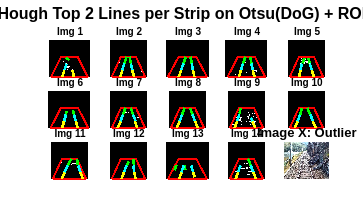

% Define the image file name
filename = 'p8.jpg'; 
folder = fullfile(pwd, 'Data'); 
filepath = fullfile(folder, filename);

% Load the image
img = imread(filepath);

% Display the image
imshow(img);

% Add title
title({'Image X: Outlier'}, 'FontSize', 10);

To address this limitation, we added an extra validation stage for images initially classified as clear, as described in the following steps:

- Rail regression

- Three-way region split

- Superpixel segmentation and Outlier detection

- Anomaly ratio for classification

### Rail Regression

Rail regression fits smooth curves to the left and right rails so we can define side and inter-rail regions. It uses the Hough line segments from the first stage and fits degree-2 polynomials through them.

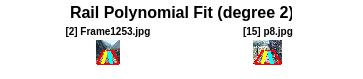

clear_idx = find(predicted_status == "Clear");

for k = 1:numel(clear_idx)
    i = clear_idx(k);
    
    % Get preprocessed binary image for this image
    bw_clean = images_otsu_dog_roi_clean{i};
    [h, w] = size(bw_clean);
    
    % Build ROI mask (trapezoid)
    roi_x = [ROI_BL_X*w, ROI_BR_X*w, ROI_TR_X*w, ROI_TL_X*w];
    roi_y = [h, h, ROI_TOP_Y*h, ROI_TOP_Y*h];
    roi_mask = poly2mask(roi_x, roi_y, h, w);
    
    % Call your auxiliary function
    [left_pts, right_pts, left_segments, right_segments, ...
     x_left_fit, x_right_fit, y_fit, p_left, p_right] = ...
        aux_rail_regression(bw_clean, roi_mask, n_strips, ...
        theta_min, theta_max, x_thresh);
    
    % Use outputs (e.g. store for later steps)
    rail_fits{i} = struct('left_pts', left_pts, 'right_pts', right_pts, ...
        'left_segments', {left_segments}, 'right_segments', {right_segments}, ...
        'x_left_fit', x_left_fit, 'x_right_fit', x_right_fit, ...
        'y_fit', y_fit, 'p_left', p_left, 'p_right', p_right, ...
        'roi_x', roi_x, 'roi_y', roi_y);
end

% Build minimal results struct for plotting
results.clear_idx = clear_idx;
results.rail_fits = rail_fits;
results.filenames = filenames;

% Plot rail regression for clear images 1 and 2 only
plot_rail_regression(results, images, [1, 9]);

### Three-way region split

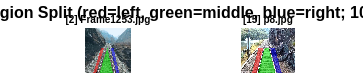

clear_idx = find(predicted_status == "Clear");

rail_padding = 20;
pct_side = 0.10;

N = length(images);
region_left   = cell(N, 1);
region_middle = cell(N, 1);
region_right  = cell(N, 1);

for k = 1:numel(clear_idx)
    i = clear_idx(k);

    [h, w, ~] = size(images{i});
    rf = rail_fits{i};
    p_left = rf.p_left;
    p_right = rf.p_right;

    [left_region, mid_region, right_region] = aux_three_way_regions(h, w, ...
        p_left, p_right, ROI_TOP_Y, rail_padding, pct_side);

    region_left{i}   = left_region;
    region_middle{i} = mid_region;
    region_right{i}  = right_region;
end

% Build minimal results struct for plotting
results.clear_idx = clear_idx;
results.region_left   = region_left;
results.region_middle  = region_middle;
results.region_right  = region_right;
results.filenames = filenames;
results.roi_params = struct('pct_side', pct_side, 'rail_padding', rail_padding);

% Plot 3-way regions for clear images 1 and 9
plot_three_way_regions(results, images, [1, 9]);

### Superpixel segmentation and Outlier detection

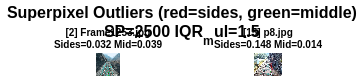

clear_idx = find(predicted_status == "Clear");

num_superpixels = 2500;
sp_compactness  = 10;
iqr_multiplier  = 1.5;

N = length(images);
anomaly_maps   = cell(N, 3);
anomaly_ratios = nan(N, 2);
sp_labels_all  = cell(N, 3);

for k = 1:numel(clear_idx)
    i = clear_idx(k);
    img = images{i};
    if size(img, 3) == 1
        img = repmat(img, [1 1 3]);
    end

    [anom_left, anom_mid, anom_right, sp_labels, r_sides, r_mid] = ...
        aux_superpixel_and_outliers(img, region_left{i}, region_middle{i}, region_right{i}, ...
        num_superpixels, sp_compactness, iqr_multiplier);

    anomaly_maps{i, 1} = anom_left;
    anomaly_maps{i, 2} = anom_mid;
    anomaly_maps{i, 3} = anom_right;
    anomaly_ratios(i, 1) = r_sides;
    anomaly_ratios(i, 2) = r_mid;
    sp_labels_all{i, 1} = sp_labels{1};
    sp_labels_all{i, 2} = sp_labels{2};
    sp_labels_all{i, 3} = sp_labels{3};
end

% Build minimal results struct for plotting
results.clear_idx = clear_idx;
results.region_left   = region_left;
results.region_middle = region_middle;
results.region_right  = region_right;
results.anomaly_maps  = anomaly_maps;
results.anomaly_ratios = anomaly_ratios;
results.sp_labels_all = sp_labels_all;
results.filenames = filenames;
results.sp_params = struct('num_superpixels', num_superpixels, 'iqr_multiplier', iqr_multiplier);

% Plot superpixel outliers for clear images 1 and 9
plot_superpixel_outliers(results, images, [1, 9]);

### Anomaly ratio for classification

clear_idx = find(predicted_status == "Clear");

area_thresh_final = 0.1;

final_status = aux_anomaly_classification(predicted_status, anomaly_ratios, area_thresh_final);

% Build minimal results struct (for consistency; no plot for step 4)
results.clear_idx = clear_idx;
results.final_status = final_status;
results.anomaly_ratios = anomaly_ratios;
results.filenames = filenames;

% Final summary table
N = length(images);
img_names = cell(N, 1);
for i = 1:N
    [~, fname, ext] = fileparts(filenames{i});
    img_names{i} = [fname ext];
end
final_summary = table((1:N)', img_names, predicted_status, ...
    anomaly_ratios(:,1), anomaly_ratios(:,2), final_status, ...
    'VariableNames', {'Image', 'Filename', 'InitialClass', 'SidesRatio', 'MiddleRatio', 'FinalClass'});
disp(final_summary);

    Image         Filename         InitialClass    SidesRatio    MiddleRatio     FinalClass 
    _____    __________________    ____________    __________    ___________    ____________

      1      {'cortada11.png' }    "Obstructed"          NaN            NaN     "Obstructed"
      2      {'Frame1253.jpg' }    "Clear"          0.032284       0.039112     "Clear"     
      3      {'Frame1291.jpg' }    "Clear"          0.025374     0.00021322     "Clear"     
      4      {'Frame1532.jpg' }    "Clear"           0.04697       0.068593     "Clear"     
      5      {'Frame1603.jpg' }    "Clear"          0.011029       0.030247     "Clear"     
      6      {'Frame1616.jpg' }    "Obstructed"          NaN            NaN     "Obstructed"
      7      {'image00756.jpg'}    "Clear"         